- Create a MATLAB script called [quaternion_basics_homework.m]. On it, do the following tasks.

- Store, in $r_1$, the value of a rotation of $\phi =\frac{\pi \;\;}{8}\;\textrm{rad}$ about the x-axis.

- Store, in $r_2$, the value of a rotation of $\phi =\frac{\pi \;\;}{16}\;\textrm{rad}$ about the y-axis.

- Store, in $r_3$, the value of a rotation of $\phi =\frac{\pi \;\;}{32}\;\textrm{rad}$ about the z-axis.

- Calculate the result of the sequential rotation of the neutral reference-frame by $r_1$, followed by $r_2$, followed by $r_3$, and store it in ${\mathit{\mathbf{r}}}_4$. Plot ${\mathit{\mathbf{r}}}_4$.

- Find the reverse rotation of ${\mathit{\mathbf{r}}}_4$ and store it in ${\mathit{\mathbf{r}}}_5$.

- Rotate ${\mathit{\mathbf{r}}}_5$ by ${360}^{\circ \;}$ about the x-axis and store it in ${\mathit{\mathbf{r}}}_6$. Is ${\mathit{\mathbf{r}}}_5 =-{\mathit{\mathbf{r}}}_6$? Plot ${\mathit{\mathbf{r}}}_5$ and ${\mathit{\mathbf{r}}}_6$ to confirm that they represent the same rotation.

include_namespace_dq


r1=cos(pi/16)+i_*sin(pi/16)

r1 = 
         0.98079 + 0.19509i


r2=cos(pi/32)+j_*sin(pi/32)

r2 = 
         0.99518 + 0.098017j


r3=cos(pi/64)+k_*sin(pi/64)

r3 = 
         0.9988 + 0.049068k


r4=r1*r2*r3

r4 = 
         0.97395 + 0.19863i + 0.086491j + 0.066992k


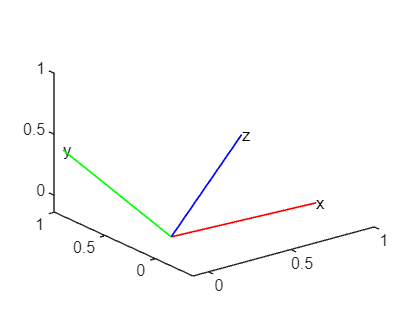

ans = struct with fields:
    handle_axis: {[1×1 Line]  [1×1 Line]  [1×1 Line]}
    handle_text: {[1×1 Text]  [1×1 Text]  [1×1 Text]}


plot(r4)

r5=conj(r4)

r5 = 
         0.97395 - 0.19863i - 0.086491j - 0.066992k


r6=r5*(cos(pi)+i_*sin(pi))

r6 = 
          - 0.97395 + 0.19863i + 0.086491j + 0.066992k


if r5 == -r6
    disp("true");
end

true
